# Atividade 8 - Análise de Sinais Discretos

## Boas práticas

clear;                %%% limpando as variáveis
close all;            %%% fechando todas as figuras
clc;                  %%% limpando a tela

## Variáveis Simbólicas

syms t s tau w

## Função de Entrada x(t)

%%% Entrada com a Função xt - Pulso unitário
xt = heaviside(t);

## Transformada de Fourier

%%% Sistema - filtro passa baixa 
Gw = 1/(1j*w+1)

$$Gw = \frac{1}{1+w\,\mathrm{i}}$$

%%% Trsnformada da entrada
Xw = fourier(xt, t, w)

$$Xw = \pi \,\delta (w)-\frac{\mathrm{i}}{w}$$

%%% Saída em Laplace
Yw = Gw * Xw

$$Yw = \frac{\pi \,\delta (w)-\frac{\mathrm{i}}{w}}{1+w\,\mathrm{i}}$$

%%% Saída sem tempo
ytw = ifourier(Yw, w, t)

$$ytw = \frac{\pi +\pi \,\mathrm{sign}\left(t\right)-\pi \,{\mathrm{e}}^{-t}\,\left(\mathrm{sign}\left(t\right)+1\right)}{2\,\pi }$$

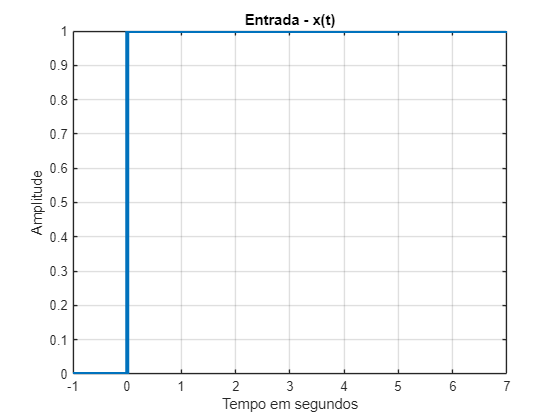

%%% Plotagem do sinal de entrada
fplot(xt, [-1,7], 'LineWidth', 3)
title('Entrada - x(t)')
xlabel('Tempo em segundos')
ylabel('Amplitude')
grid

## Laplace

%%% Sistema - filtro passa baixa
Gs = 1/(s+1)

$$Gs = \frac{1}{s+1}$$

%%% Função Original
gt = ilaplace(Gs, s, t)

$$gt = {\mathrm{e}}^{-t}$$

%%% Transformada da Entrada
Xs = laplace (xt, t, s)

$$Xs = \frac{1}{s}$$

%%% Saída em Laplce
Ys = Gs * Xs

$$Ys = \frac{1}{s\,\left(s+1\right)}$$

%%% Saída sem tempo 
yts = ilaplace(Ys, s, t)

$$yts = 1-{\mathrm{e}}^{-t}$$

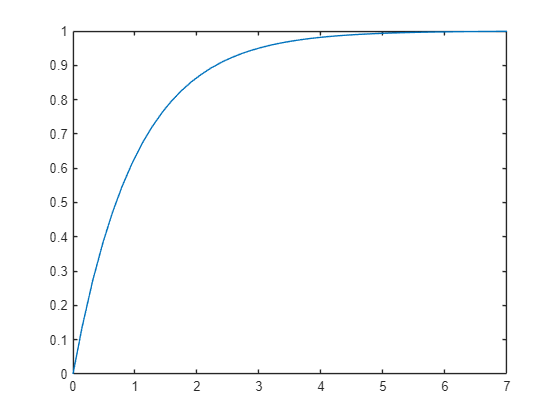

fplot(yts, [0,7])

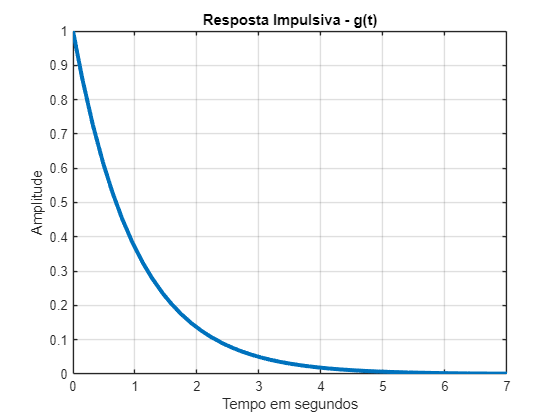


%%% Plotagem da Resposta Impulsiva
fplot(gt, [0,7], 'LineWidth', 3)
title('Resposta Impulsiva - g(t)')
xlabel('Tempo em segundos')
ylabel('Amplitude')
grid

## Convolução

%%% Sinal g de tau
gconv = subs(gt, t,tau);

%%% Convolução com os dois sinais usando a integral
yconv = int(gconv*heaviside(t-tau),tau,0,t)

$$yconv = \frac{\mathrm{sign}\left(t\right)}{2}-\frac{{\mathrm{e}}^{-t}}{2}-\frac{{\mathrm{e}}^{-t}\,\mathrm{sign}\left(t\right)}{2}+\frac{1}{2}$$

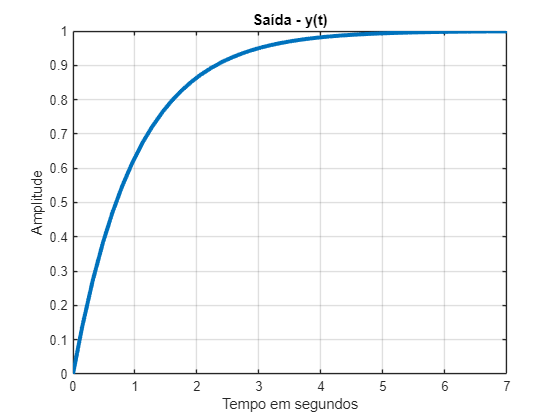

%%% Plot da função de Convolução entre os dois sinais
fplot(yconv, [0 7], 'LineWidth', 3)
title('Saída - y(t)')
xlabel('Tempo em segundos')
ylabel('Amplitude')
grid

## Pontos notáveis 

### Ponto 1

ponto_1_0 = double(subs(yts, 1))

ponto_1_0 = 0.6321

ponto_1_1 = double(subs(yconv, 1))

ponto_1_1 = 0.6321

ponto_1_2 = 1 - exp(-1)

ponto_1_2 = 0.6321

### Ponto 2

ponto_2_0 = double(subs(yts, 2))

ponto_2_0 = 0.8647

ponto_2_1 = double(subs(yconv, 2))

ponto_2_1 = 0.8647

ponto_2_2 = 1 - exp(-2)

ponto_2_2 = 0.8647